# Preprocess ECG Signal

In this script, we will import, visualise and analyse ECG signal and build suitable preprocessing algorithm to have a quantative ECG signal.

### Step 1: Load the ECG signal and plot signal Data

load ecgSignals.mat
%Signal Parameters
fs=2000 %sampling rate =2000Hz

fs = 2000

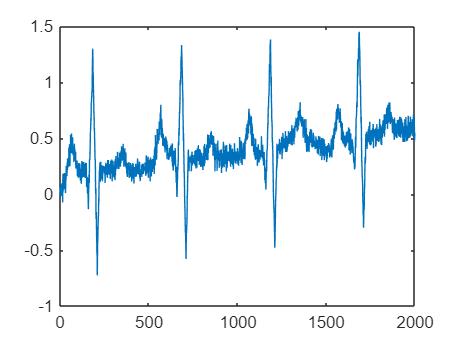

t=0:fs-1;
ECGsig=ecgl;
%Visualise the ECG signal
plot(t,ECGsig);

#### Observations:

- Our baseline is abnormal(The baseline has a positive trend)

- Throughout the signal, in low amplitude regions, we have high frequency noise.

### Step 2: Eliminate the trend in Signal Data

The MATLAB function 'detrend' helps you identify the trend and remove the trend.

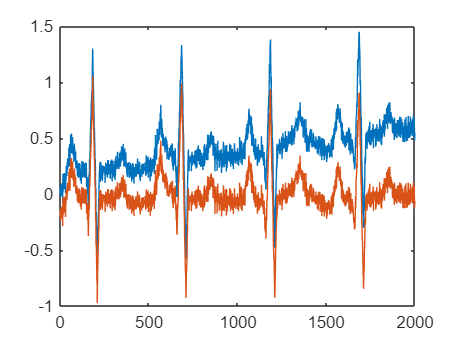

Detrended_signal=detrend(ECGsig);
plot(t,ECGsig,t,Detrended_signal);

legend('Original ECG signal','Detrended ECG signal','Location','Southside');

Error using legend (line 245)
Error setting property 'Location' of class 'Legend':
'Southside' is not a valid value. Use one of these values: 'north' | 'south' | 'east' | 'west' | 'northeast' | 'northwest' | 'southeast' | 'southwest' | 'northoutside' | 'southoutside' | 'eastoutside' | 'westoutside' | 'northeastoutside' | 'northwestoutside' | 'southeastoutside' | 'southwestoutside' | 'best' | 'bestoutside' | 'none' | 'layout'.

### Step 3: Convert Time domain data to Frequency Domain

    [pxx,fxx]=pwelch(Detrended_signal,fs);
    plot(fxx,pxx);
    xlabel('Frequency');
    ylabel('Power');
    title('Spectrum of detrended ECG signal');
    

### Step 4: Design Low pass filter with automatic coding

Fs = 2000;  % Sampling Frequency

N     = 5;   % Order
Fpass = 75;  % Passband Frequency
Apass = 1;   % Passband Ripple (dB)

% Construct an FDESIGN object and call its CHEBY1 method.
h  = fdesign.lowpass('N,Fp,Ap', N, Fpass, Apass, Fs);
Hd = design(h, 'cheby1');

### Step 5: Apply filter to Signal

filteredsignal=filter(Hd,Detrended_signal);
%Frequency domain verification
[ff,pf]=pwelch(filteredsignal,fs);
plot(pf,ff);
%Time Domain Visualisation
plot(t,Detrended_signal,t,filteredsignal);
legend('Deterended ECG signal','Filtered ECG signal','Location','Southside');


### Step 6: Perform Filter Delay Compensation

filter_output_nodelay=fi;tfilt(Hd.sosMatrix,Hd.ScaleValues,designal);
plot(t,designal,t,filter_output_nodelay);